# Can a Flow from Recovered to Susceptible Explain Second Wave Effects?

### By Ian Eykamp and Ari Porad for ModSim 2020

## Question

For this project, we chose to answer the first question: Can recovered people becoming re-infectable (able to be re-infected) explain why we often observe multiple waves of a disease? This explanation will be successful if varying the rate of the flow from Recovered to Susceptible creates a variety in the lengths of delay between the first and second waves of infection in the model.

For example, the seasonal flu regularly mutates such that immunity doesn't last year-to-year, therefore allowing people to get re-infected over time.

We think this information could be useful to the medical community and to public health authorities responsible for managing outbreaks. If this model can explain the second wave phenomenon--along with additional study of the disease in question--public health authorities might want to target Non-Pharmaceutical Interventions (NPIs) at managing resusceptibility. Additionally, it may help direct what to study when a new disease appears.

## Method/Model

For this model, we adopted the SIR model from Worksheet 2 and added another flow from the Recovered stock to the Susceptible stock. The rate of this flow is modeled as a proportion of recovered people who become resusceptible per week, as the proportionality constant Δ (delta) coefficient.

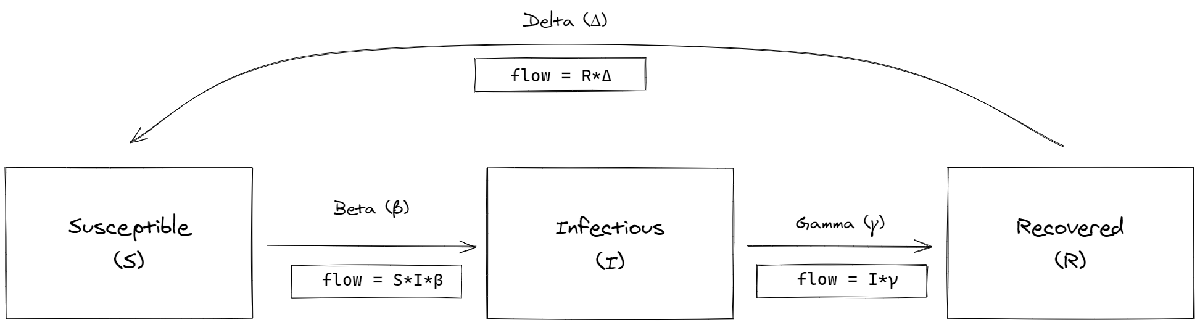

Given that the verison of this model without the Delta flow **cannot** produce a second wave effect, if the version with the Delta flow can be demonstrated to produce a second wave effect, then we know the Delta flow is one possible explaination for that effect.

### **Assumptions**

As with any model, we made some assumptions in the making of this model to reduce complexity. These assumptions include:

- We assume that the pouplation can be infinitely divided (we use arbitrarily small percentages).

- We assume that all flows are linear (to the proportionality constants, and to the stocks).

- We assume that all proportionality constants (beta, gamma, and delta) remain constant throughout the entire duration of the model.

- We assume that the population is constant (there are no births, no deaths, no immigration, no emmigration, and nobody gets vaccinated).

### **Abstractions**

- Not considering individual people (% of population)

- Not counting individual behevior

- Only modeling on a weekly basis

- Assuming black-and-white line between S, I, and R, and that the transition is instantaneous

- We compute all flows based on current populations (ex. not basing recovered on # of infectious people two weeks ago)

### **Verification**

- TODO (Facts + Proofs)

- Conservation of people

- No negative flows

- Prove that nothing changes in equilibrium

#### Conservation of People

Given Assumption #4, the number of people in the population must remain constant. To verify this, here's a run of the model with the number of people plotted each week.

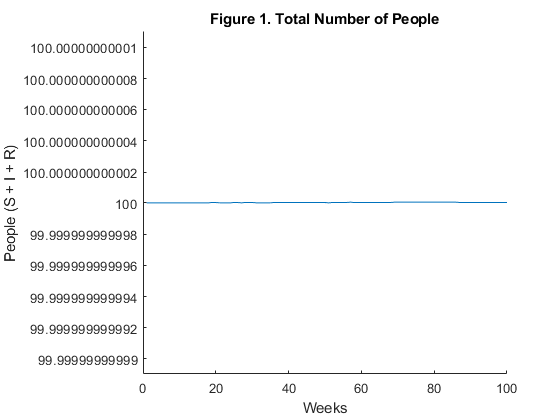

beta  = 0.01 ; % Infection Rate (S -> I, Default: 0.01)
gamma =  0.51 ; % Recovery Rate  (I -> R, Default: 0.5)
delta =0.03; % Re-susceptibility Rate (R -> S, Default: 0.03)

weeks =  100 ; % Duration of the Simulation (Default: 100)

i_0 = 1   ; % Percentage of People Starting Infected (Default: 1)
s_0 = 100 - i_0; % Everyone who isn't infected starts off susceptible 
r_0 = 0;


[S, I, R, W] = sir_simulate_noround(s_0, i_0, r_0, beta, gamma, delta, weeks);

clf; hold on;

plot(W, S + I + R);
title("Figure 1. Total Number of People")
xlabel("Weeks")
ylabel("People (S + I + R)")

## Results

Now that we've got our model, let's see what it says.

### Start with the Basics

As a baseline, here's a version of our model without the delta flow (this is the same model as Worksheet 2). Feel free to fiddle with the parameters and see how the model responds:

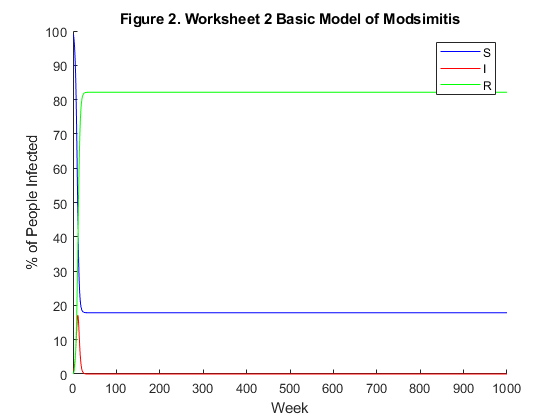

beta  =0.01 ; % Infection Rate (S -> I, Default: 0.01)
gamma = 0.51 ; % Recovery Rate  (I -> R, Default: 0.5)
delta = 0                               ; % No Delta Flow  (R -> S)

i_0 = 1     ; % Percentage of People Starting Infected (Default: 1)
s_0 = 100 - i_0; % Everyone who isn't infected starts off susceptible 
r_0 = 0;

weeks = 1000; % duration of the simulation

plot_model(s_0, i_0, r_0, beta, gamma, delta, weeks, false);
title("Figure 2. Worksheet 2 Basic Model of Modsimitis");

Notice that the outbreak has one peak before dying out, at which the model enters permanent equilibrium.

### Adding the Delta Flow

Here's the same model, but with the delta flow turned on. Again, feel free to fiddle with delta or with the parameters above to see how the model reacts.

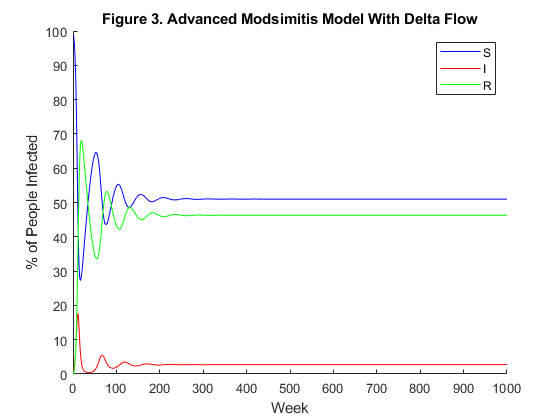

delta =0.03; % Re-susceptibility Rate (R -> S, Default: 0.03)

plot_model(s_0, i_0, r_0, beta, gamma, delta, weeks, false);
title("Figure 3. Advanced Modsimitis Model With Delta Flow");

Notice that a second wave of infection appears. We'll explore this more below.

### Delta Sensitivity Analysis

Since we know that most people don't change the defaults and therefore haven't seen how different values for delta affect the model, let us show you a graph of infection rates over time for various values of delta:

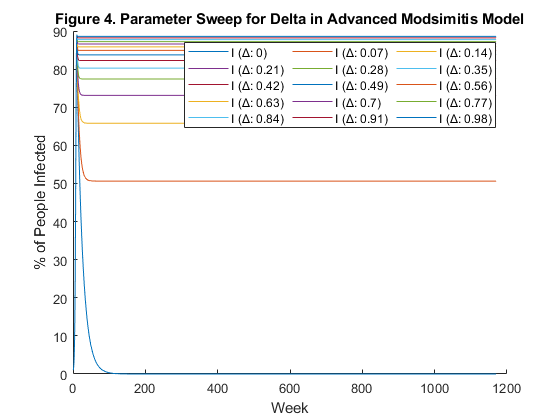

delta_min  =   0; % Smallest Value for Delta (Default: 0)
delta_max  =   0.988; % Largest Value for Delta (Default: 0.4)
delta_step = 0.07; % Step for Delta Values Between delta_min & delta_max (Default: 0.05)
only_plot_infected = true; % Makes the graph substantially easier to read

gamma = 0.06; %
weeks =1170; %

% Define the sweep range
deltas = delta_min:delta_step:delta_max;

plot_model(s_0, i_0, r_0, beta, gamma, deltas, weeks, only_plot_infected);
title("Figure 4. Parameter Sweep for Delta in Advanced Modsimitis Model");

We see that different values of delta result in different sizes and locations for the second wave. However, for all values of delta, the system eventually stabilizes at a constant number of people infected. For values of delta that result in more than two waves, each wave is substantially smaller than the previous one. Smaller (but non-zero) values of Delta result in more prominent second waves but lower eqilibrium infection rates, while higher values of Delta result in less prominent second waves but higher equilibrium infection rates.

### Let's Take a Look at the Second Peaks

Since the thing we're really interested in with the delta flow is its effects on the second wave of infection, let's look at this directly. Here's a graph of the times and heights of the second peak infection value. As always, feel free to fiddle with the sliders above to adjust the graph:

**NB:** Depending on the settings you've picked for the model, there may be points at the origin of this graph. This represents the value(s) of delta for which no second peak occurs.

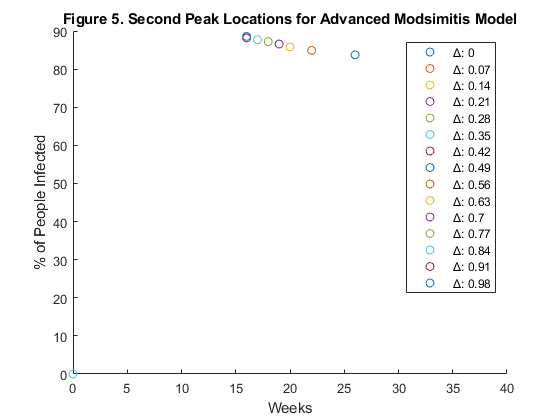

clf; 
hold on;

peaks = zeros(2, length(deltas));
labels = strings(length(deltas), 1);

for i = 1:length(deltas)
    delta = deltas(i);
    [S, I, R, W] = sir_simulate(s_0, i_0, r_0, beta, gamma, delta, weeks, @sir_step_noround);
    [pks, locs] = findpeaks(I);
    
    labels(i) = "Δ: " + num2str(delta);

    targetPeak = 2;    
    if length(locs) >= targetPeak % if two or more peaks exist 
        x = W(locs(targetPeak));
        y = I(locs(targetPeak));
        plot(x, y, "o");
        
        peaks(1, i) = x;
        peaks(2, i) = y;
        
    else
        plot(0, 0, "o");
    end
end

legend(cellstr(labels));
title("Figure 5. Second Peak Locations for Advanced Modsimitis Model")
xlabel("Weeks")
ylabel("% of People Infected");

We see that different values of Delta produce differently-sized peaks at different points in time. Additionally, we can see that those peaks, when plotted on a percent-infected-vs-time graph, seem to follow some sort of curve. Let's look more closely at that pattern.

### How Does the Value of Delta Affect the Size and Location of the Second Peak?

Now that we've seen that changing the value of delta has an affect on the second peaks, let's take a closer look at exatly how the value of delta affects the size and location of the second peak:

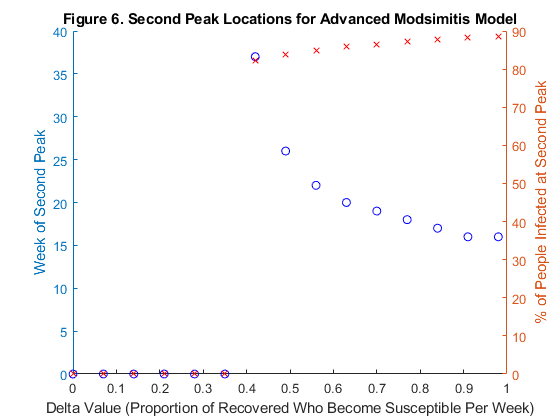

figure; clf; hold on;

yyaxis left;
plot(deltas, peaks(1, :), 'bo');
ylabel("Week of Second Peak");

yyaxis right;
plot(deltas, peaks(2, :), 'rx');
ylabel("% of People Infected at Second Peak");
title("Figure 6. Second Peak Locations for Advanced Modsimitis Model")
xlabel("Delta Value (Proportion of Recovered Who Become Susceptible Per Week)");

From this plot, we can see that the height of the second peaks, i.e. the percentage of people infected, increases nearly linearly with an increase in the delta value. Meanwhile, the week number of the second peak, i.e. the length of time between the first and second peaks, decreases approximately as an exponential function of the delta value. This means that for very small value of delta, the second wave can be made to occur an arbitrarily long time after the first infection wave. As we saw earlier, this wave will also be highly prominent compared with the weeks preceding and following it, albeit a smaller peak than the first wave. We propose that smaller values of delta may be more realistic for modeling diseases with seasonal variation or long delays between outbreaks.

## Interpretation

The addition of an appropriate flow from recovered to susceptible creates a periodic series of infection waves that diminish in height over the course of the model. For higher values of delta, the infection never reaches close to zero, and the model quickly reaches an equilibrium point between the S, I, and R stocks, and the flows between them. For low values of delta, the waves are more prominent, and the number of infected cases drops to a negligible value between each wave. This means the disease has all but disappeared from the population, providing time for the population to become more fully susceptible again before the cycle reapeats.

However, two major assumptions limit the scope of applicability of this model to real-life situations. First, it does not allow subsequent waves of infection to be as high as the first wave, which in the real world is only true for certain diseases. Sometimes, as in this model, a portion of the population can be expected to retain immunity, but other diseases change so significantly that nearly everyone becomes re-susceptible at once. 

Secondly, since the model does not incorporate introduction of the disease from outside, all new infections must originate from within the population. In the model, the disease lives on in between waves in only minute amounts for low values of delta. A more complete model would provide criteria for eradication after which point the disease would cease to cause infections except for re-introduction from outside. In this case, then, the flow from recovered to susceptible does not *cause* the second and subsequent waves; instead, it creates the conditions under which a second wave is possible.